# Basket

Use MATLAB with Python to play with NBA data

**Resources**

- [https://github.com/swar/nba_api](https://github.com/swar/nba_api) 

### Games

games = readtable("games-2015-2024.csv")

games = 10749x8 table
    GAME_ID     GAME_DATE         MATCHUP         WL      PTS    PLUS_MINUS     TEAM      OPPONENT
    ________    __________    _______________    _____    ___    __________    _______    ________

    2.15e+07    2015-10-27    {'CHI vs. CLE'}    {'W'}     97         2        {'CHI'}    {'CLE'} 
    2.15e+07    2015-10-27    {'ATL vs. DET'}    {'L'}     94       -12        {'ATL'}    {'DET'} 
    2.15e+07    2015-10-27    {'GSW vs. NOP'}    {'W'}    111        16        {'GSW'}    {'NOP'} 
    2.15e+07    2015-10-28    {'PHX vs. DAL'}    {'L'}     95       -16        {'PHX'}    {'DAL'} 
    2.15e+07    2015-10-28    {'POR vs. NOP'}    {'W'}    112        18        {'POR'}    {'NOP'} 
    2.15e+07

records = calculate_elo(games)

records = 10749x8 table
       date       game_id      team      opponent    elo_pre    elo_opp_pre    elo_diff     win 
    __________    ________    _______    ________    _______    ___________    ________    _____

    2015-10-27    2.15e+07    {'CHI'}    {'CLE'}       1500         1500           100     true 
    2015-10-27    2.15e+07    {'ATL'}    {'DET'}       1500         1500           100     false
    2015-10-27    2.15e+07    {'GSW'}    {'NOP'}       1500         1500           100     true 
    2015-10-28    2.15e+07    {'PHX'}    {'DAL'}       1500         1500           100     false
    2015-10-28    2.15e+07    {'POR'}    {'NOP'}       1500       1492.8         107.2     true 
    2015-10-28    2.15e+

### Prep data

% Feature matrix (X) and target vector (y)
X = records(:, {'elo_pre', 'elo_opp_pre', 'elo_diff'});
y = records.win;

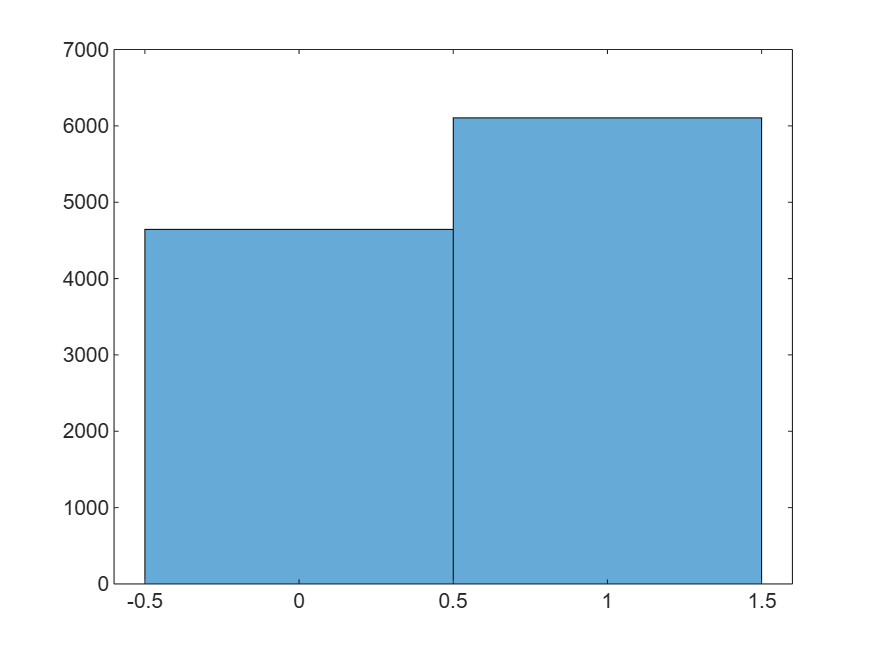

histogram(y)

### Classification

classificationLearner

The models are overpredicting wins, probably because the dataset is unbalanced